### Define Input

f_input = [10 1000];
ASD_input = 0.001*[ones(1,2)];

F0 = max(10, f_input(1)); %initial frequency
Fr = 0.2; %interpolation resolution
Fmax = min(1000, f_input(end)); % final frequency
Fs = 2*f_input(end);

f = F0:Fr:Fs/2;
PSD = exp(interp1(log(f_input), log(ASD_input), log(f), 'linear'));
Grms = sqrt(trapz(PSD)*Fr);

## Response

fn = 20; %[Hz]
zeta = 1/100;

TF_abs = @(f) sqrt( (1+(2*zeta*f/fn).^2)./( (1-(f/fn).^2).^2+(2*zeta*f/fn).^2 ));

TF_mag = TF_abs(f);
Response = TF_mag.^2 .* PSD;

Grms_Response = sqrt(trapz(Response)*Fr);

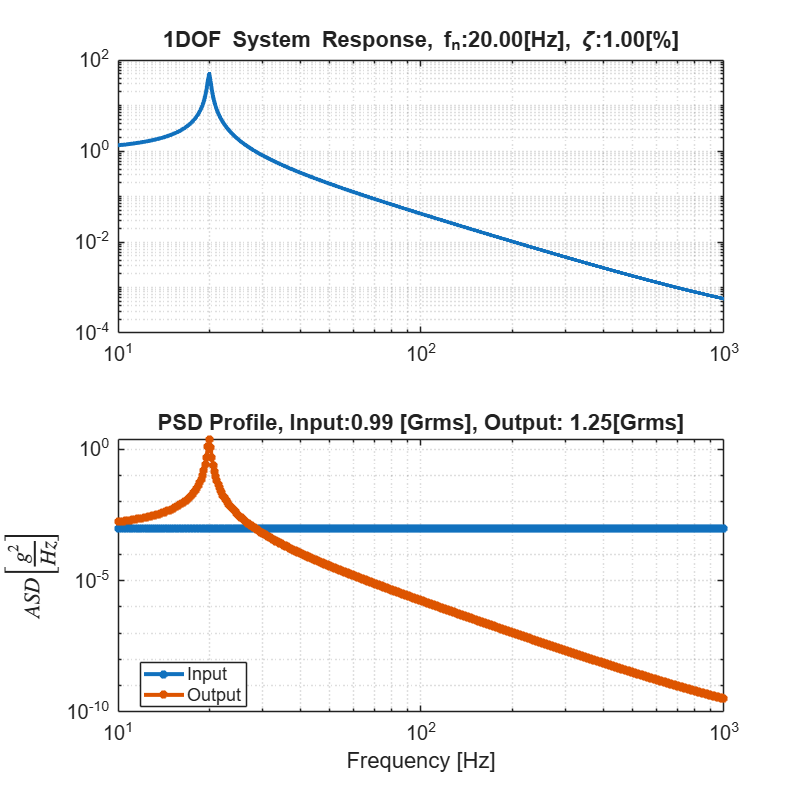

figure('Position',[0 0 800 800])
ax(1) = subplot(211);
loglog(f, TF_mag, 'LineWidth',3);
title(sprintf('1DOF System Response, f_n:%.2f[Hz], \\zeta:%.2f[%%]', fn, zeta*100), 'Interpreter','tex')
grid minor

ax(2) = subplot(212);

loglog(f, PSD, '-*','LineWidth',3, 'DisplayName',  'Input');
hold on
loglog(f, Response, '-*','LineWidth',3, 'DisplayName',  'Output');
grid minor

ylabel('$ASD \left[\frac{g^2}{Hz}\right]$', 'Interpreter','latex')
xlabel('Frequency [Hz]')
title(sprintf('PSD Profile, Input:%.2f [Grms], Output: %.2f[Grms]', Grms, Grms_Response))
legend('show', 'Location','best')

set(ax, 'fontsize', 15)

Miles Approximation

Grms_Miles = sqrt(pi/2*fn*1/(2*zeta)*PSD(f==fn))

Grms_Miles = 1.2533